# piDMD w/ dimensional reduction via LSUN for Conservative systems

References

- Baddoo Peter J., Herrmann Benjamin, McKeon Beverley J., Nathan Kutz J. and Brunton Steven L. 2023Physics-informed dynamic mode decompositionProc. R. Soc. A.4792022057620220576, http://doi.org/10.1098/rspa.2022.0576

- Kutz JN, Brunton SL, Brunton BW, Proctor JL. 2016 *Dynamic mode decomposition: data-driven modeling of complex systems*. Philadelphia, PA: SIAM.

clear 
close all

## Source Data Preparation

load("../../../data/databook_DATA/DATA/VORTALL");
U = reshape(VORTALL,199,449,[]);

## Source Data Visualization

clims = 1.1*[min(U,[],'all') max(U,[],'all')];
nFrames = size(U,3);
him = [];
for iFrame = 1:nFrames
    x = U(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);
    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
    end
    drawnow
end

## Noisy Data Preparation

Noise energy set to 20% of signal energy

varu = var(U,0,"all");
varw = 0.2*varu; 
% sigmau = sqrt(varu);
sigmaw = sqrt(varw);
V = U + sigmaw * randn(size(U),'like',U);

## Noisy Data Visualization

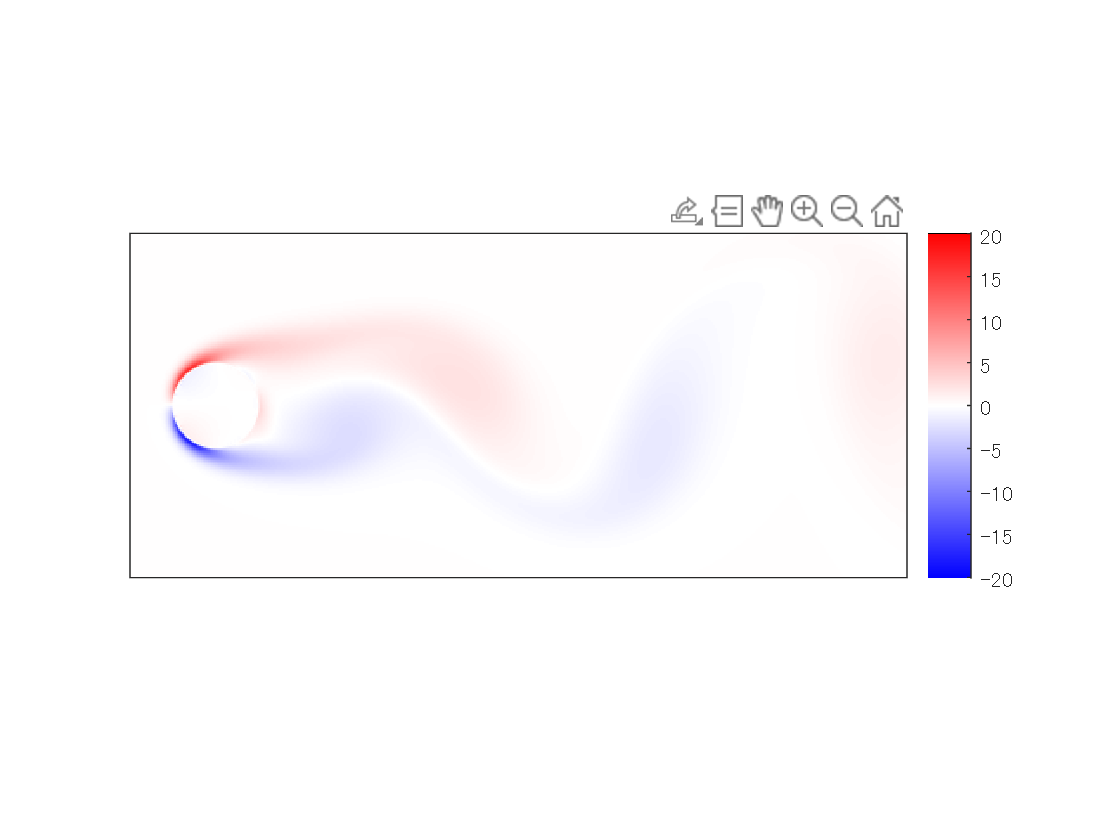

him = [];
for iFrame = 1:nFrames
    x = V(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);

    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
    end
    drawnow
end

## Experiments (piDMD w/ leading POD mode truncation)

## Experiments (piDMD w/ dimensional reduction via LSUN)

## Definition of Drawing Function

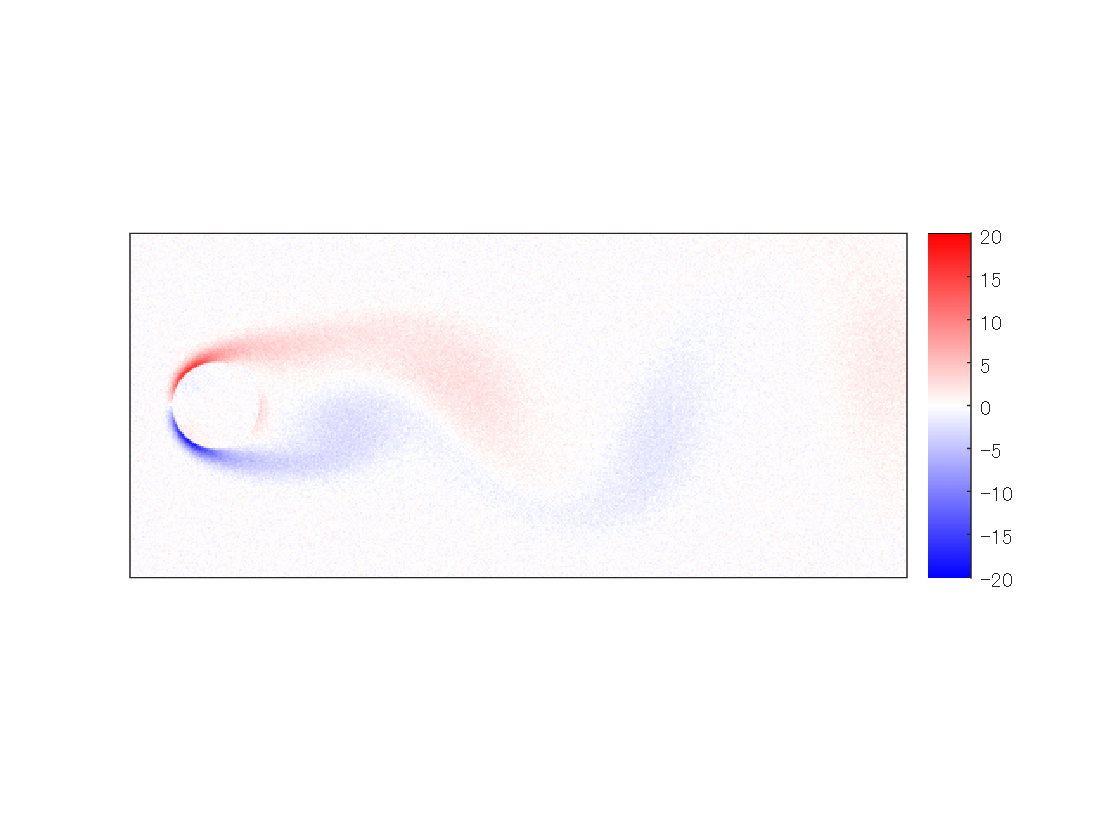

function him = mycylinderplot_(him,x,clims)
if isempty(him)
    figure
    him = imagesc(x,clims);
    axis equal
    axis tight
    ax = gca;
    ax.XTick = [];
    ax.YTick = [];
    cmap = zeros(256,3);
    cmap(128:255,1) = 1;
    cmap(1:127,3) = 1;
    hsv = rgb2hsv(permute(cmap,[1 3 2]));
    hsv(:,2) = [254:-2:0 1:2:255].'/255;

    cmap = ipermute(hsv2rgb(hsv),[1 3 2]); 
    colormap(cmap)
else
    him.CData = x;
end
end